# **SCPI - Control Programmable Instrument with SCPI via Serial Interface**

This example shows how to use the SCPI PSU block to control a programmable instrument using RS-232 serial communication. All the ASCII commands are managed directly by the SCPI PSU block.

## Introduction 

SCPI is an ASCII-based instrument command language designed for test and measurement instruments.

Simulink® Real-Time™ and Speedgoat hardware provide you with a convenient platform to easily and remotely control selected programmable power supplies using Serial Communication.

This example uses the RS-232 interface of the RTTM [OnBoard Serial](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_serial_onboard) to remotely control a programmable power supply, the TDK Lambda GENH. The serial communication can be achieved also with other [Serial I/O Modules](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io50Xio581).

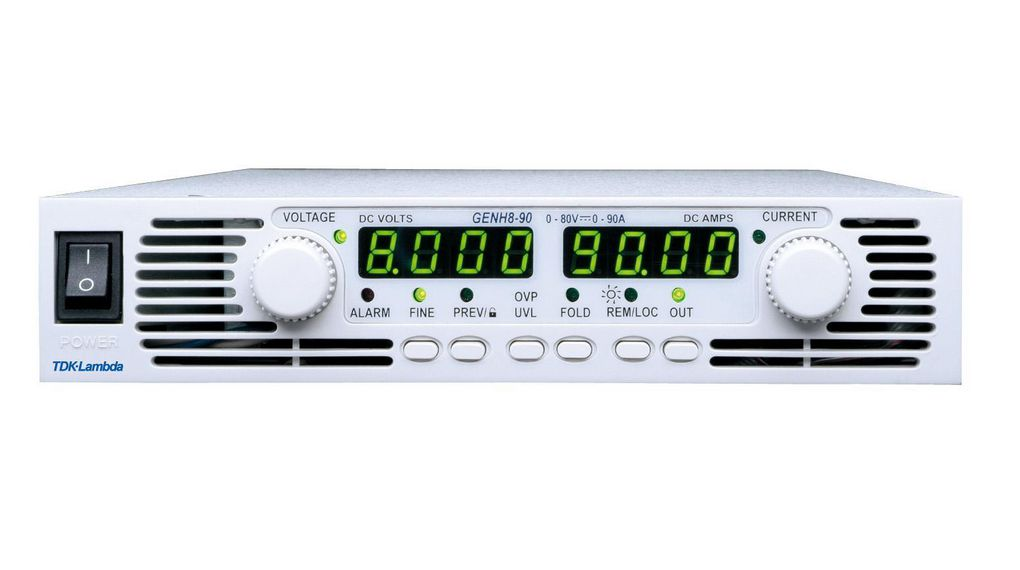

## Setup

### Prerequisites

You require the following to run this example:

- A Speedgoat real-time target machine

- A Connector cable from the DSUB-9 Serial port of the RTTM to the RJ45 Serial port of the TDK Lambda PSU.

To identify the baudrate and address of the power supply, click the front panel button REM/LOC for three seconds. Adjust the Simulink model accordingly.

## Initialize and Open the Simulink Model

*Add commands to configure parameters and other settings.*

 
% Open Simulink model
modelName = 'sgMdl_SCPI_PSU_Serial';
open_system(modelName);

## Example Overview

In this example, a basic understanding of the workings of this [SCPI PSU block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_scpi_psu) are exposed. Daisy-chain option is not explored, and the only possibility to have a stuck communication is if the RTTM is not correctly (or at all) connected to the TDK Lambda GENH power supply.

In this example the SCPI PSU block will send and receive all the messages through the OnBoard Serial interface, that needs to be connected to it in the model.

### Model Start

At the beginning of the model execution, the block will send a general reset command GRST with the carriage return termination ('\r', 0d13 in ASCII) that does not need to initialize the communication with the device. Then it will wait the indicated 200ms before starting to send the commands from the model. The Model Start configuration can be found in the "Options" tab.

### Normal execution

To initialize the communication with the TDK Lambda PSU, that in this case has the address 6, the SCPI PSU block will send the string "ADR 6", and it will continue with the command for that device only when it confirms the good communication. Since in this example all the commands are for the same device, no more communication initialization are necessary, but the "ADR x" command has to be executed every time that the target device changes.

After the initialization, the commands are being sent one by one, and before sending the next, the SCPI PSU block must receive the expected value. If the command sent was a request, the response will be displayed on the equivalent output port. When the end of the command list has been reached, only the commands that have the input value changed will be sent.

### Model Stop

When the model is stopped, by the user, model error, or just the end of the model time is reached, the ModelStop message will be sent by the Serial Write block. In this case the suggested message to be copied in the [Serial Write block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_write) is the same as the initial message, the GRST command with the carriage return termination ('\r', 0d13 in ASCII), that will reset all the TDK Lambda GENH power supplies connected to that serial port. The option "Wait for the TX FIFO to empty" is chosen, to let any possible messages still in the Serial FIFO to be sent correctly by their entirety, so to have a correct elaboration of the commands before sending the reset command.

### Special ports

Since no errors or unexpected messages are planned in this example, the Drain output port should not display anything. On the other end, the ClearToSend output port should show a '1' to indicate that the block is ready to send the next message, and the LastCmdIdx output port should show the index of the last sent command, so if the user did not change the input values of the commands, at the end of the model execution this should display the number '6'.

## Model Description

To function correctly, the [SCPI PSU block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_scpi_psu) needs the read/write block from a serial interface connected to it. To ensure a timely execution, is better to keep the [Read block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_read) at the left of the SCPI block, and the [Write block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_write) at its right.

Except the "Skip Cmd" and "Retry Cmd" input ports that is of the type "uint8", all the other Const blocks are "double", so decimals and negative numbers are allowed.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode
% set_param(modelName, 'SimulationCommand', 'start')      % start real-time application through Simulink toolstrip

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;


## Conclusion

This example showed how to:

- Configure the RS-232 interface

- Send SCPI commands and queries to a programmable instrument with RS-232 interface in real-time

- Receive SCPI query responses from a programmable instrument with RS-232

This would be the serial port exchange in the example, where the messages with '>>' are the one being sent by the SCPI PSU block, and the ones with '<<' are the responses from the device. Here the carriage returns are implicitly '\r' at the end of each message, sent or received.

- >>GRST

- >>ADR 6

- <<OK

- >>PV 7

- <<OK

- >>OUT 1

- <<OK

- >>MV?

- <<7.0000

- >>PC 0.5

- <<OK

- >>MC?

- <<0.000

- >>CLS

- <<OK

- >>GRST

## Additional References

- [SCPI examples and documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_scpi_landing)